set(0,'defaultAxesTickLabelInterpreter','latex');
set(0,'defaultTextInterpreter','latex'); set(0,'defaultLegendInterpreter','latex');
AR = 8.5;
Sweep = 0;
Taper = 0.531;
c_bar = 3.58;
srefref = 101.925;
fuselage_rad = 1.25;
%29.1548
%% discritize planform to plot
[Sref, c_y, span_disc,quarterchord,MACpos] = planformcalc(AR, Sweep, Taper, c_bar)

Sref = 102.5302

c_y =     4.5370    4.5356    4.5341    4.5327    4.5313    4.5298    4.5284    4.5269    4.5255    4.5241    4.5226    4.5212    4.5197    4.5183    4.5168    4.5154    4.5140    4.5125    4.5111    4.5096    4.5082    4.5068    4.5053    4.5039    4.5024    4.5010    4.4995    4.4981    4.4967    4.4952    4.4938    4.4923    4.4909    4.4895    4.4880    4.4866    4.4851    4.4837    4.4822    4.4808    4.4794    4.4779    4.4765    4.4750    4.4736    4.4722    4.4707    4.4693    4.4678    4.4664


span_disc =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


quarterchord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


MACpos = 665

MACcord = span_disc(MACpos)

MACcord = 6.6400

longitudinalMACac =  4;
fuselagedatum = 0

fuselagedatum = 0

feselageend = 15

feselageend = 15

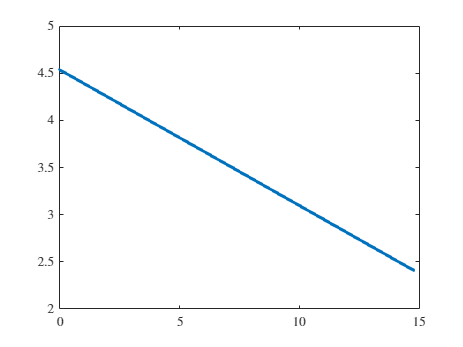



plot(span_disc,c_y,'.')

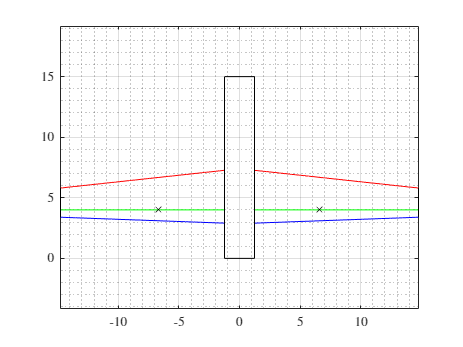

% x_engine = quarterchord(ceil(length(c_y)*0.37))
% height_engine0.37*max(span_disc)*tand(5)-0.175*c_y(ceil(length(c_y)*0.37))-0.9
LEsweep = (quarterchord-quarterchord(MACpos) + longitudinalMACac) - 0.25 .* c_y;
TEsweep = (quarterchord-quarterchord(MACpos) + longitudinalMACac) + 0.75 .* c_y;
quarterchordplot = (quarterchord-quarterchord(MACpos) + longitudinalMACac);
%origin at quarterchord point of root chord
plot (span_disc(fuselage_rad*100:end),LEsweep(fuselage_rad*100:end),'b')
hold on
plot (span_disc(fuselage_rad*100:end),TEsweep(fuselage_rad*100:end),'r')
plot (span_disc(fuselage_rad*100:end),quarterchordplot(fuselage_rad*100:end),'g')
plot (span_disc(MACpos),quarterchordplot(MACpos),'xk')

plot (-span_disc(fuselage_rad*100:end),TEsweep(fuselage_rad*100:end),'r')
hold on
plot (-span_disc(fuselage_rad*100:end),LEsweep(fuselage_rad*100:end),'b')
plot (-span_disc(fuselage_rad*100:end),quarterchordplot(fuselage_rad*100:end),'g')
plot (-span_disc(MACpos),quarterchordplot(MACpos),'xk')

plot ([span_disc(fuselage_rad*100),span_disc(fuselage_rad*100)], [LEsweep(fuselage_rad*100),TEsweep(fuselage_rad*100)],'k')
plot ([span_disc(end),span_disc(end)], [LEsweep(end),TEsweep(end)],'k')
plot ([-span_disc(fuselage_rad*100),-span_disc(fuselage_rad*100)], [LEsweep(fuselage_rad*100),TEsweep(fuselage_rad*100)],'k')
plot ([-span_disc(end),-span_disc(end)], [LEsweep(end),TEsweep(end)],'k')

plot ([span_disc(fuselage_rad*100),span_disc(fuselage_rad*100)],[fuselagedatum,feselageend],'k')
plot ([-span_disc(fuselage_rad*100),-span_disc(fuselage_rad*100)],[fuselagedatum,feselageend],'k')
plot ([-span_disc(fuselage_rad*100),span_disc(fuselage_rad*100)],[fuselagedatum,fuselagedatum],'k')
plot ([-span_disc(fuselage_rad*100),span_disc(fuselage_rad*100)],[feselageend,feselageend],'k')

ylim([-7.5 7.5])
axis equal
hold off
grid on
grid minor

chordpos = 0;
[Sweep_c] = sweepcalc(LEsweep,chordpos,c_y,span_disc)

Sweep_c = 2.0640

function [Sref, c_y,span_disc,quarterchord,MACpos] = planformcalc(AR, Sweep, Taper, c_bar)
s_1 = 0.25 * AR * (1+Taper); %_1 using 1 as reference root chord length
Sref_1 = (1 + Taper) * s_1;
span_disc_1 = [0:0.01:s_1];
c_y_1 = 1 - ((1-Taper)/s_1) * span_disc_1;
c_bar_1 = 2*trapz(span_disc_1,(c_y_1).^2)/Sref_1;
ratio = c_bar/c_bar_1; % dimensionalize using c_bar, can be changed later to root or tip chord length
s = ratio*s_1;
Sref = ratio * (1 + Taper) * s;
span_disc = [0:0.01:s];
c_y =  (1 - ((1-Taper)/s) * span_disc)*ratio;
temp1 = (c_y - c_bar).^2;
MACpos = find(temp1 == min(temp1));
quarterchord =  span_disc .* tand(Sweep);
end

function [Sweep_c] = sweepcalc(LEsweep,chordpos,c_y,span_disc)
sweeppos = LEsweep + chordpos .* c_y;
Sweep_c = atand((sweeppos(end)-sweeppos(1))/(span_disc(end)-span_disc(1)));
end

function [CL_alpha_curve] = easyCLcurve(Cl_alpha, Mach, Sweep, AR, S_rat, FLF,yetaest)
beta = (1-Mach^2)^0.5;
if yetaest == 0
    yeta = Cl_alpha/(2*pi/beta);
else
    yeta = yetaest;
end
CL_alpha_curve = 2*pi*AR/(2+(4+((AR^2*beta^2)/(yeta^2))*(1+(tand(Sweep))^2/(beta^2)))^0.5) * S_rat * FLF;
end

function [Re] = easyreynolds1(height,refl,machnum,velo)
[T,a,p,rho] = atmosisa(height);
if machnum == 0
    mu = 2.791*10^(-7) * T ^(0.7355);
    Re = rho * refl * velo / (mu);
elseif machnum ~= 0
    mu = 2.791*10^(-7) * T ^(0.7355);
    Re = rho * machnum * refl * a / (mu);
end
end